# Report - Exercise C3 from TP2

## Looking at our samples

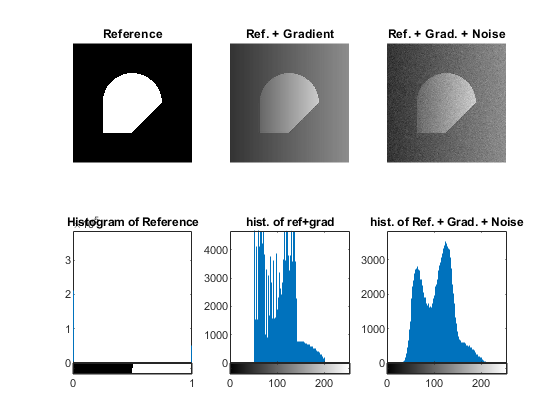

%obtaining samples, GT's, and results
GT     = imread('seg1.jpg'); GT       = im2bw(GT, 0.5); 
graded = imread('seg2.jpg'); ASgrad   = RuiCampos_TP2_C2('seg2.jpg', 10, 0);
noisy  = imread('seg3.jpg'); ASnoisy  = RuiCampos_TP2_C2('seg3.jpg', 10, 0);

%looking at the samples
figure('Name', 'The Samples')
subplot(2,3,1), imshow(GT), title('Reference')
subplot(2,3,4), imhist(GT), title('Histogram of Reference')

subplot(2,3,2), imshow(graded), title('Ref. + Gradient')
subplot(2,3,5), imhist(graded), title('hist. of ref+grad')

subplot(2,3,3), imshow(noisy), title('Ref. + Grad. + Noise')
subplot(2,3,6), imhist(noisy), title('hist. of Ref. + Grad. + Noise')

Our reference(ground truth) is a binary synthetic image already. We also have a version of that image with a gradient applied to it, and then that graded image with what looks like a gaussian noise on top of it.

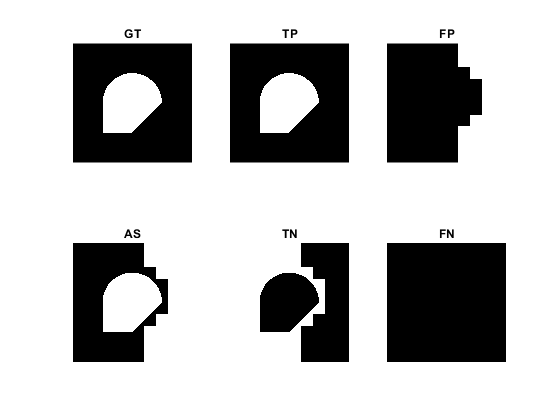

%determining TP, TN, FP, FN
TPgrad  = ASgrad  & GT;    TPnoisy  = ASnoisy & GT;
TNgrad  = ~(ASgrad  | GT); TNnoisy  = ~ (ASnoisy | GT);
FPgrad  = ASgrad & (~GT);  FPnoisy  = ASnoisy & (~GT);
FNgrad  = (~ASgrad) & GT;  FNnoisy  = (~ASnoisy) & GT;

%checking to see if it worked
figure('Name', 'Result of Set Operations - for graded')
subplot(2,3,1), imshow(GT),     title('GT')
subplot(2,3,4), imshow(ASgrad), title('AS')

subplot(2,3,2), imshow(TPgrad), title('TP')
subplot(2,3,5), imshow(TNgrad), title('TN')

subplot(2,3,3), imshow(FPgrad), title('FP')
subplot(2,3,6), imshow(FNgrad), title('FN')

From here I can make a qualitative assessment of the results:

- it correctly detected all the pixels in the ground truth

- to the right of the image, it falsely detected a lot of pixels due to the gradient

- correctly asessed most of the oFF pixels

- no pixes were wrongfully detected as negative (see first point)

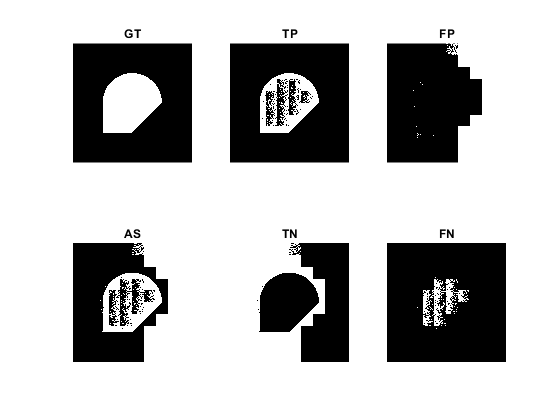

%checking to see if it worked
figure('Name', 'Result of Set Operations - for noisy')
subplot(2,3,1), imshow(GT),      title('GT')
subplot(2,3,4), imshow(ASnoisy), title('AS')

subplot(2,3,2), imshow(TPnoisy), title('TP')
subplot(2,3,5), imshow(TNnoisy), title('TN')

subplot(2,3,3), imshow(FPnoisy), title('FP')
subplot(2,3,6), imshow(FNnoisy), title('FN')

Here, we can still see the effect of the gradient, but it's worsened by the noise. This time we even have false negative. 

## Discussing the measures

We have several measures that can be applied. I'll start by briefly discussing the necessity for this variety. The simplest measure that one could come up with is to directly compare the reference to our result: compare each pixel to see if they have the same value. In this context(binary image), we're taking the pixel value to be a surrogate measure for area. Thus, by summing over the intersection, we're calculating the area of the image that was segmented correctly. By dividing by the area of the reference, we obtain the fraction of the segment that was correctly detected.


$$\mathrm{TDR} = \frac{\#(\textrm{GT} \cap \textrm{AS})}{\# \textrm{GT}}$$


However, this measure alone fails to give us a full picture of what's going on. If we calculate it for an AS that only has true values, the result would be 1, indicating perfect detection. However, it certainly is not perfect since it wrongfully detected parts of the image as being part of the segment. This motivates the introduction of a measure such as the False Positive Rate, which compares the area of the image that was wrongfully detected with the area of the correct segment. Doesn't matter if 100% of the pixels were detected, if there are 3x as many pxels that were detected outside the ground truth. 

## Evaluating the Performance

The algorithm has two inputs, one of them being S, where SxS is the number of neighborhoods considered. The most natural approach is, as suggested, to graph the error vs S, since I can vary S with ease. But there are other valid approaches. One idea would be to vary the noise and the gradient for example, and graph error against a quantitive measure for each or perhaps changing the conditions for applying local threshold. Due to time constraints, I opted to just vary S and changed the luminosity and contrast of the two samples, in the hopes that it would give me interesting results. The most adequate approach would be to synthetize my own GT, varying luminosity and contrast or any number of conditions.

From the script, in figure 1, first plot(errors vs S) we see that the following measures quickly stabilize(at around S=10):

- TDR ~ 1

- H ~ 0.75

- J ~ 0.4

- FNR ~ 0

I find it interesting that the FPR and TNR are mirrors of each other:this happens because the FP and TN sets are complements of each other(if you exclude ground truth).

They take a little longer to stabilize(at about 30). Another interesting occurence is that valley at S=2. Not quite sure why it does that. 

For the gradient with noise, it takes a little bit longer to stabilize(S~20). After that, some "jitter" can be seen in TDR that was not present in the previous graph, this is a natural consequence of the random nature of noise. 